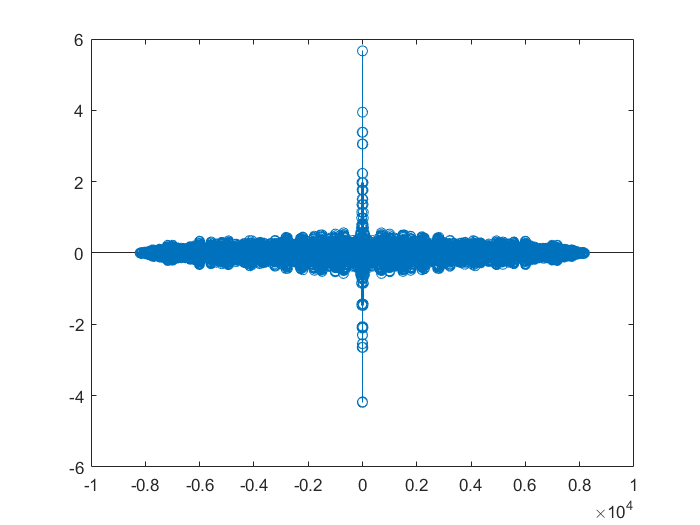

clear all;
close all;
clc;

v = randn(1, 8192);
N = length(v);
b = [1, -1];
a = [1, -1.5, 0.9]; 
x = filter(b,a,v);
my_ac(x, N);

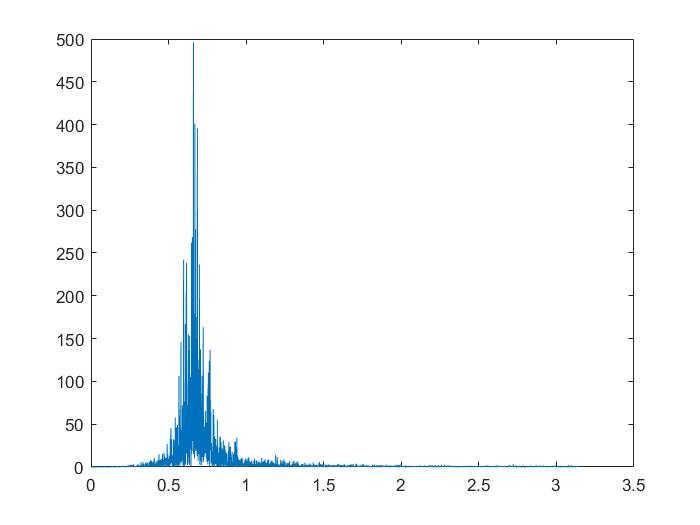

my_periodogram(x);

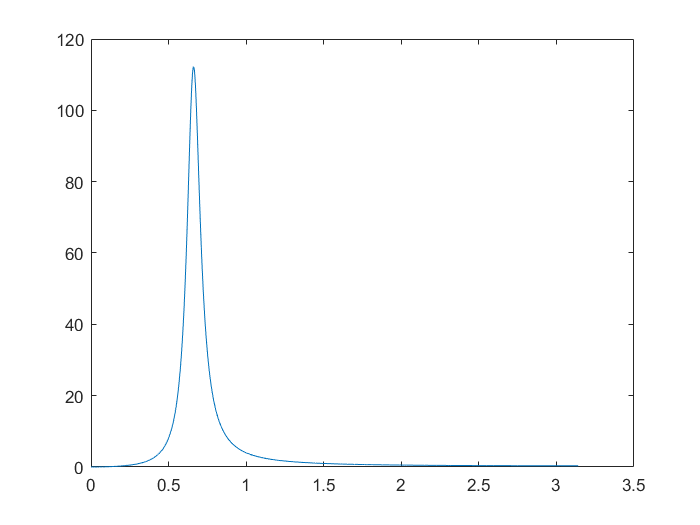

% % % % % % % % % % % % % % % % % 
% Calculate true PSD for x
[h,w] = freqz(b,a,N/2);
% h_half = h(1:N/2);
Hw_square = abs(h).^2;
Pvv_true = ones(1, N/2) * var(v);
Pxx_true = Hw_square .* Pvv_true;
w = 0:2*pi/N:(N-2)*pi/N;
plot(w, Pxx_true);